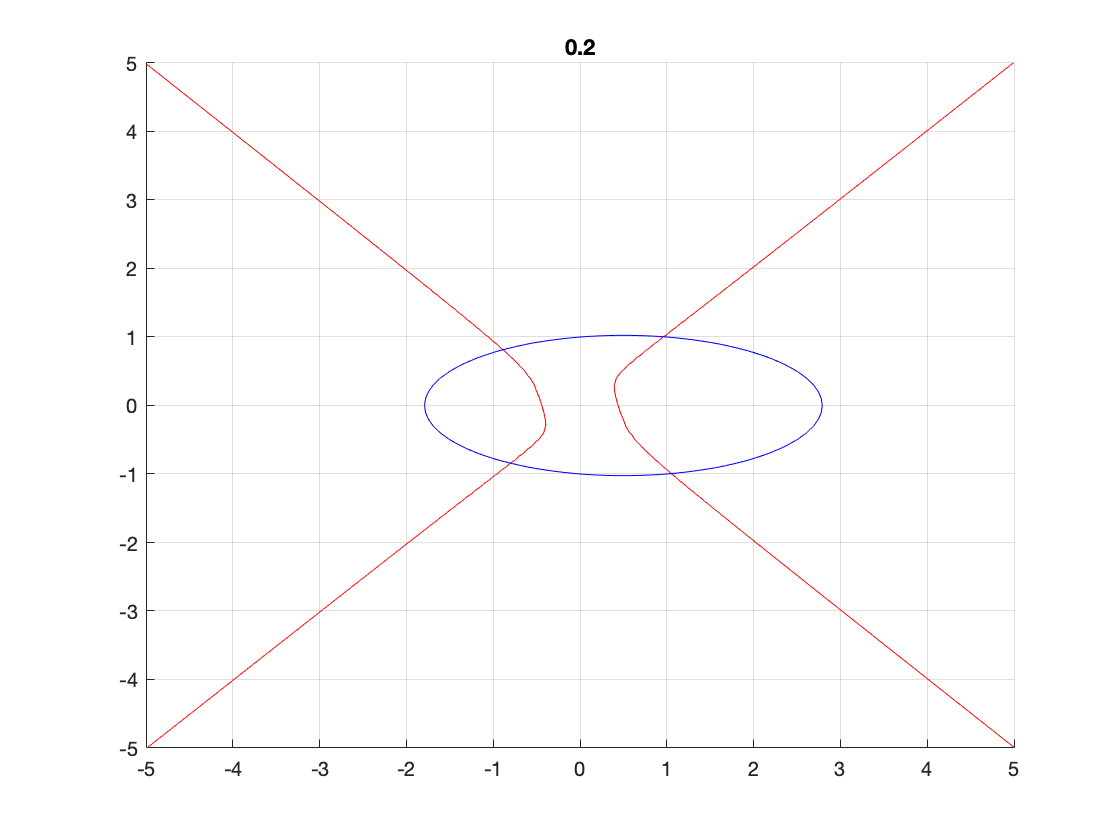

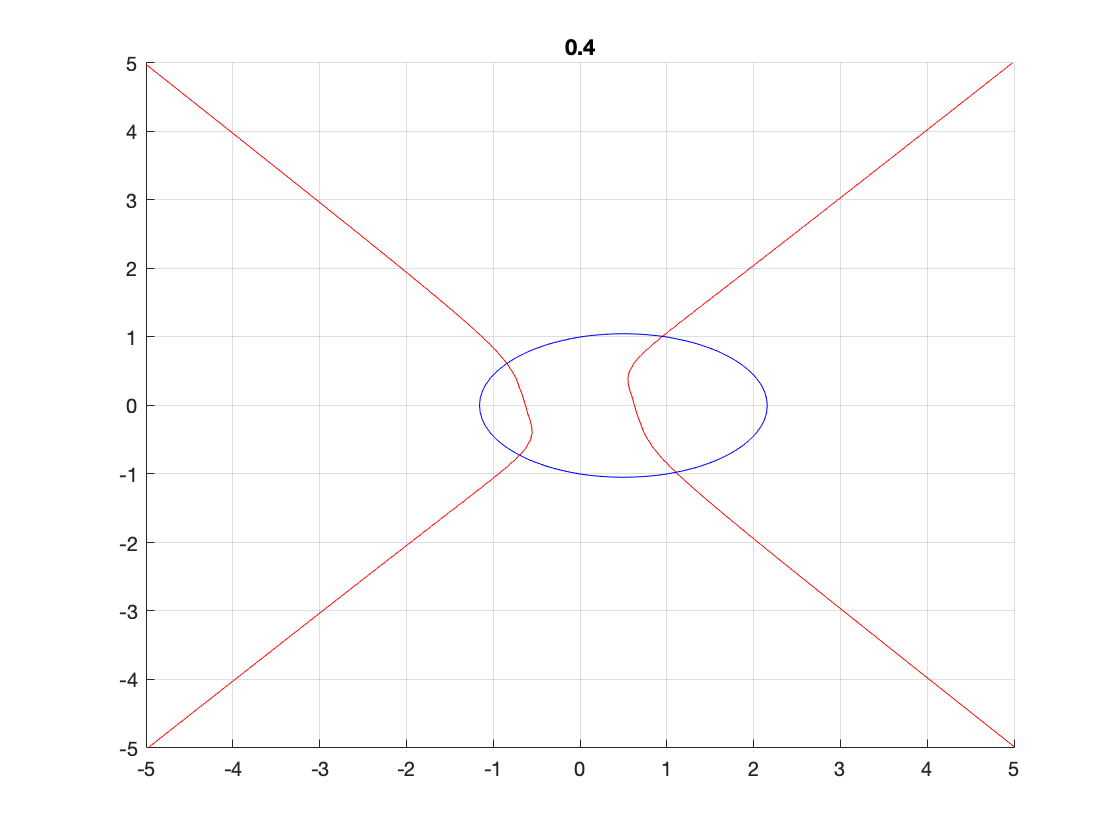

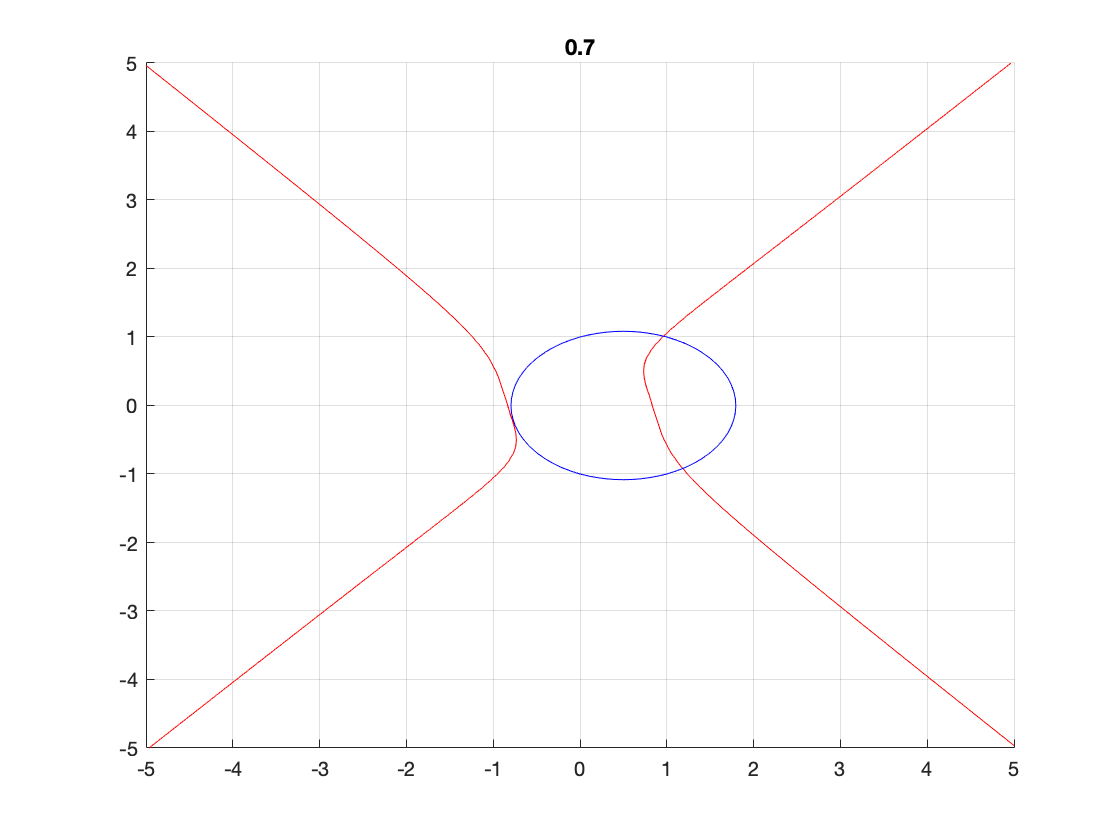

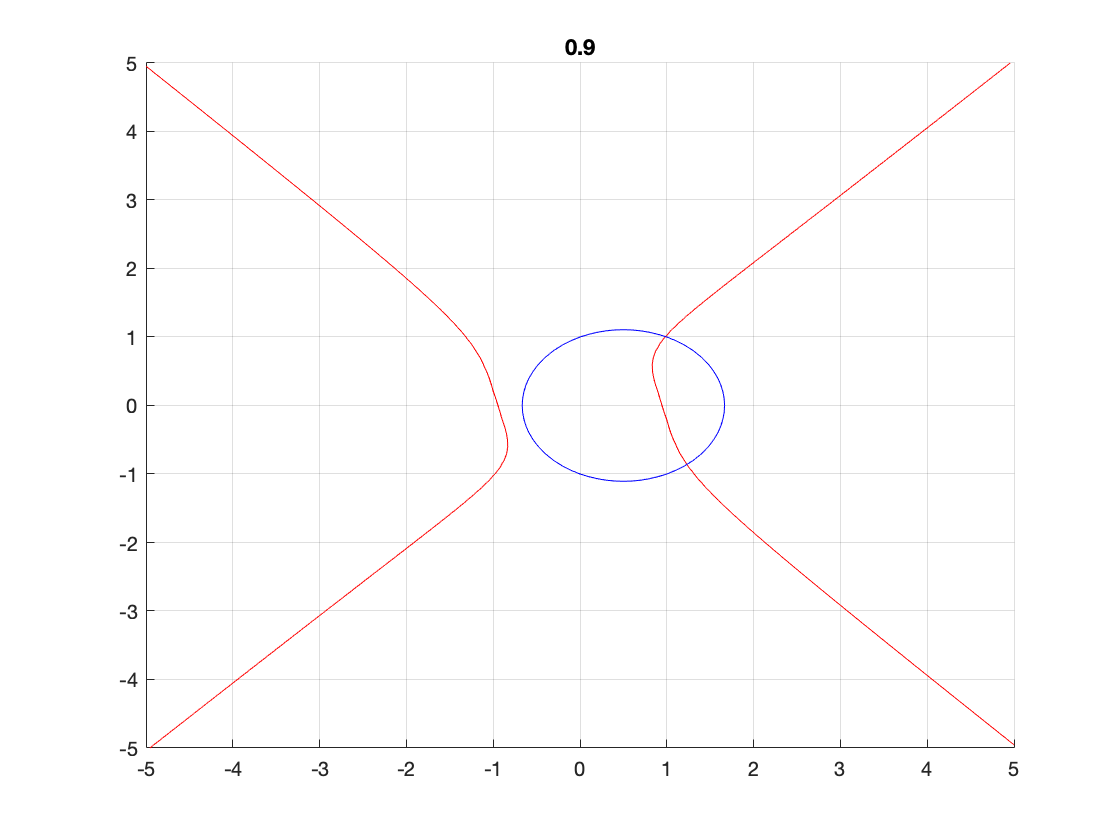

format long
delta_a = 0.1;
M       = 10;
k       = 0;

alpha    = zeros(1,M);
x_result_1 = zeros(1,M);
y_result_1 = zeros(1,M);
x_result_2 = zeros(1,M);
y_result_2 = zeros(1,M);
Jac      = zeros(1,M);

for a = 0:delta_a:delta_a*M
    
    syms x y
    F_1   = x^4 - y^4 + a*x*y - a^2;
    F_2   = a*x^2 + y^2 - a*x - 1;
    F_1_x = diff(F_1,x);
    F_2_x = diff(F_2,x);
    F_1_y = diff(F_1,y);
    F_2_y = diff(F_2,y);

    N = 10;
    x_n = zeros(1,N);
    y_n = zeros(1,N);
    x_n(1) = -1;
    y_n(1) = 1;

    for n = 1:N-1
        J = [subs(subs(F_1_x,x,x_n(n)),y,y_n(n)) subs(subs(F_1_y,x,x_n(n)),y,y_n(n));
         subs(subs(F_2_x,x,x_n(n)),y,y_n(n)) subs(subs(F_2_y,x,x_n(n)),y,y_n(n))];
        B = [subs(subs(F_1,x,x_n(n)),y,y_n(n)); subs(subs(F_2,x,x_n(n)),y,y_n(n))];
        X_n = [x_n(n);y_n(n)];
        X = X_n - inv(J)*B;
        x_n(n+1) = X(1);
        y_n(n+1) = X(2);
    end
    
    k = k + 1;
    if((k == 3) | (k == 5) | (k == 8) | (k == 10))
        figure(k);
        hold on; grid on;

        F=@(t,s)t.^4 - s.^4 + a.*t.*s - a.^2;
        t=-5:0.1:5;
        s=-5:0.1:5;
        [X,Y]=meshgrid(t,s);
        contour(X,Y,F(X,Y),[0,0],'r');

        F=@(t,s)a*t.^2 + s.^2 - a.*t - 1;
        t=-5:0.1:5;
        s=-5:0.1:5;
        [X,Y]=meshgrid(t,s);
        contour(X,Y,F(X,Y),[0,0],'b');
        
        title(a)
    end
    
    alpha(k)    = a;
    x_result_1(k) = x_n(N);
    y_result_1(k) = y_n(N);
    Jac(k)      = det(J);
end


alpha

alpha =                    0   0.100000000000000   0.200000000000000   0.300000000000000   0.400000000000000   0.500000000000000   0.600000000000000   0.700000000000000   0.800000000000000   0.900000000000000   1.000000000000000


x_result_1

x_result_1 =   -1.000000000000000  -0.935337930199679  -0.889396284881434  -0.859874948870033  -0.844756481153233  -0.841181765948871  -0.840819505763728  -0.758951798997281   1.576886180894709   1.233417741193369  -0.544202401752007


y_result_1

y_result_1 =    1.000000000000000   0.904975415474371   0.814810157467084   0.721264193642467   0.613719807859051   0.474990247629500   0.267061475653280  -0.285963596520789  -1.088882596559482  -0.860748846153914  -0.583580929862125


Jac

Jac =   -8.000000000000000  -6.638340048347821  -5.621857757587544  -4.791456791233480  -4.016671003272372  -3.175133611999323  -2.118736919951826   1.125486523978843 -17.651495333081716 -16.420933429293775   8.304121500848280


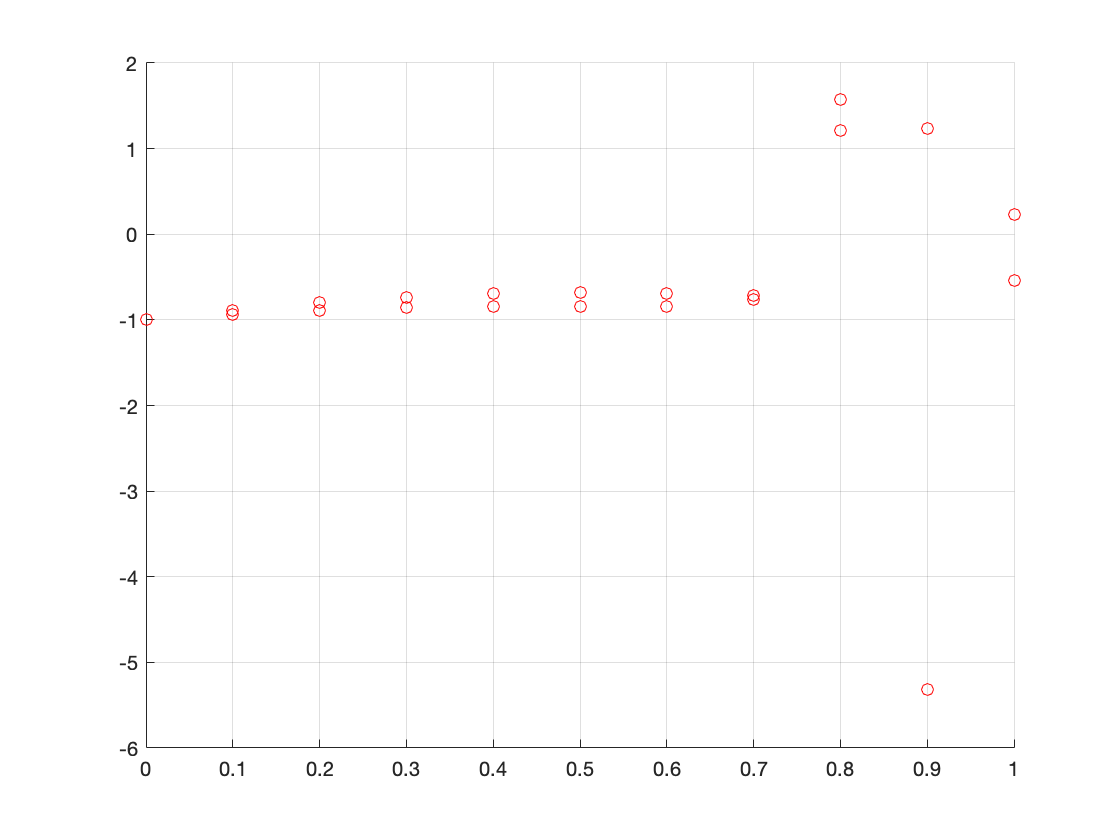

k = 0;

for a = 0:delta_a:delta_a*M
    
    syms x y
    F_1   = x^4 - y^4 + a*x*y - a^2;
    F_2   = a*x^2 + y^2 - a*x - 1;
    F_1_x = diff(F_1,x);
    F_2_x = diff(F_2,x);
    F_1_y = diff(F_1,y);
    F_2_y = diff(F_2,y);

    N = 10;
    x_n = zeros(1,N);
    y_n = zeros(1,N);
    x_n(1) = -1;
    y_n(1) = -1;

    for n = 1:N-1
        J = [subs(subs(F_1_x,x,x_n(n)),y,y_n(n)) subs(subs(F_1_y,x,x_n(n)),y,y_n(n));
         subs(subs(F_2_x,x,x_n(n)),y,y_n(n)) subs(subs(F_2_y,x,x_n(n)),y,y_n(n))];
        B = [subs(subs(F_1,x,x_n(n)),y,y_n(n)); subs(subs(F_2,x,x_n(n)),y,y_n(n))];
        X_n = [x_n(n);y_n(n)];
        X = X_n - inv(J)*B;
        x_n(n+1) = X(1);
        y_n(n+1) = X(2);
    end
   
    k = k + 1;
    x_result_2(k) = x_n(N);
    y_result_2(k) = y_n(N);
end

figure(M+1);
hold on;grid on;
plot(alpha,x_result_1,'or')
plot(alpha,x_result_2,'or')

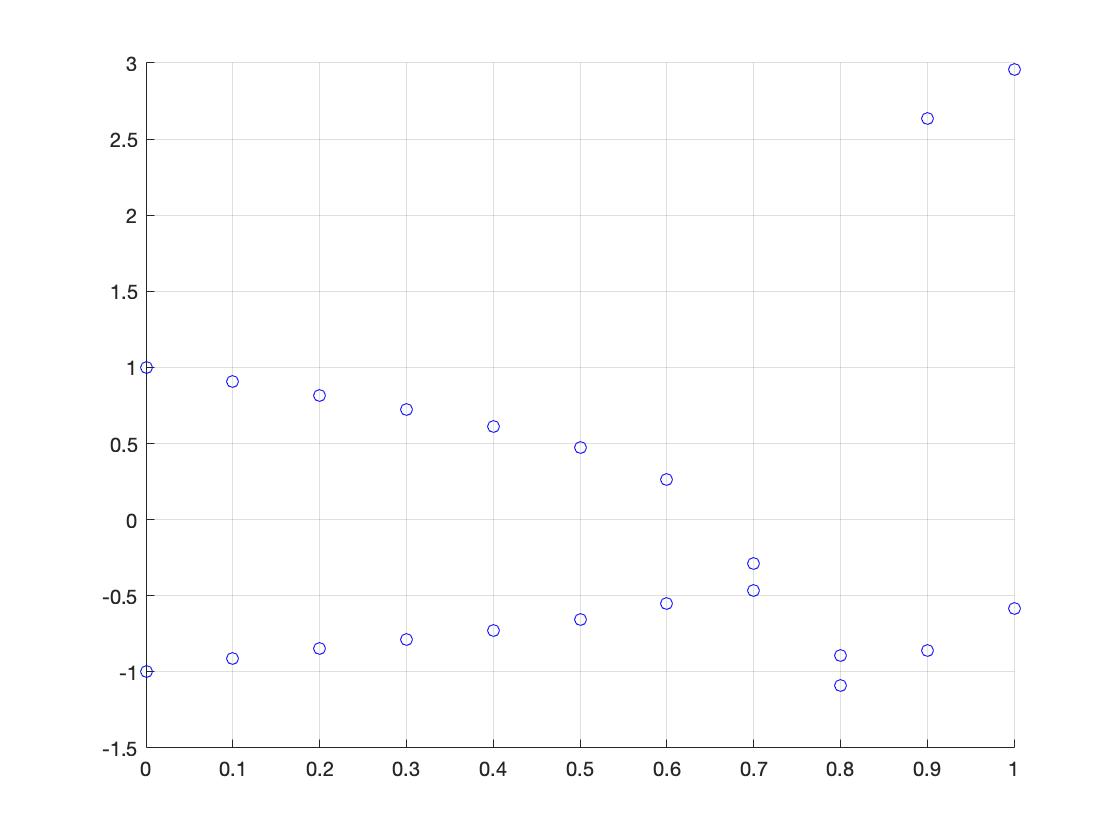


figure(M+2);
hold on;grid on;
plot(alpha,y_result_1,'ob')
plot(alpha,y_result_2,'ob')